Definizione del **numeratore** e del **denominatore** della **FdT**.

num = 1;
den = [1 -0.5];

sys = tf(num,den)


sys =
 
     1
  -------
  s - 0.5
 
Continuous-time transfer function.
Model Properties


Calcolo dei **poli** del sistema dinamico.

pole(sys)

ans = 0.5000

Tracciamento del **diagramma di Bode**.

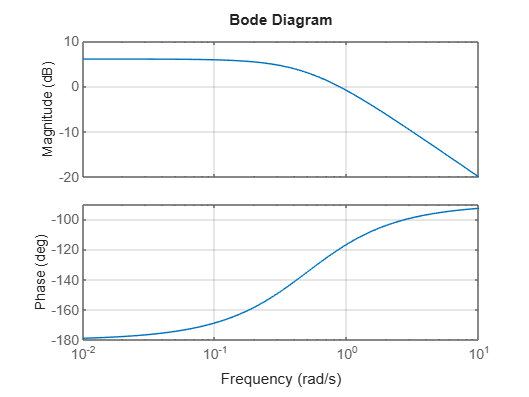

bode(sys);
grid on

Calcolo del **Margine di Guadagno** e** di Fase **della funzione.

- **Margine di Guadagno**: si calcola facendo 20log10|num| - 20log10|den| [bB] alla pulsazione ω dove la fase vale -180°.

- **Margine di Fase**: si calcola facendo arg(num) - arg(den) alla pusazione ω dove il guadagno vale 0 [dB]. **NOTA**: nel calcolo dell'angolo tramite funzione **atan()** è importante guardare il quadrante in cui si trova l'argomento dell'arcotangente: in questo caso la parte reale del denominatore è negativa (-0.5) e la parte immaginaria positiva (0.866) all'ora l'angolo è nel secondo quandrante. Calcolando l'angolo del denominatore si ottiene -60° ---> secondo quadrante: 180° - 60° = 120°. L'atan(num) = 0, si ha quindi che la fase della** FdT** vale 0° - 120° = -120°. Il **Margine di Fase** è dato da 180° + (-120°) = **60°**.  

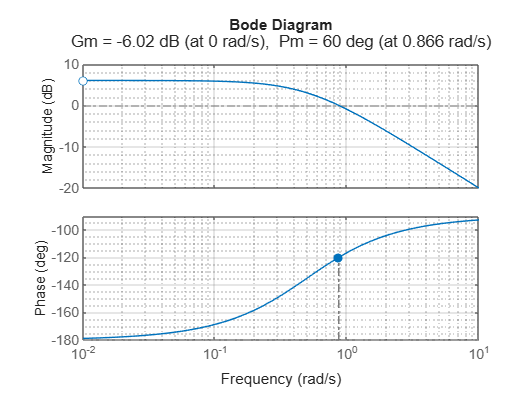

margin(sys)
grid on
grid minor